# Doyle-Fuller-Newman Model Usage Example

This script demonstrates how to use and interpret the outputs of the DFN model in the TOOFAB toolbox.

The main DFN model lives in DFN.m. It is called as:

out = DFN(input_current,tf,init_cond,param)

Inputs

`input_current` can be supplied as one of: 

- a scalar, applied constantly from `t=0` to `t=tf`,

- an array `[t I]` (optionally `[t I T]` with measured temperature in K). Interpolation/extrapolation between samples is controlled by `current_interp` and `current_extrap`,

- a function handle `@fcn` returning the next current from voltage, current, concentration and potential states (useful for closed-loop control or cycling).

`tf is` simulation length in seconds.

`init_cond` can be provided as either a scalar in `[0, 1]` (initial SoC), a scalar starting voltage, or a struct with the initial internal states `cs`, `ce`, `phis`, `phie`. If passed as a struct, the discretisation must match the simulation discretisation.

`param` *(optional)* is the DFN model parameter set. If omitted, the defaults at the bottom of `DFN.m` are used.

The examples below progress from the simplest call to dynamic profiles, function-handle cycling, and finally BPX parameter import. Ageing is present in `DFN.m` but not exercised here. Model-simplification trade-offs are touched on briefly; see [Khalik et al., 2021] and the user manual for a full treatment.

Before we use the script, we first add the main TOOFAB folder to our filepath, such that we can run the example without requiring an independent copy of DFN.m in our current working folder. 

addpath('../..')

## Example 1: Constant-Current Discharge with default parameters

A 5 A discharge for 12 000 s, starting at 100 % SoC, using the default parameter set.

out = DFN(-5,12000,1);

15:38:28 Starting simulation...
15:38:36 Finished the simulation in 7.83 s 



The output struct `out` contains the time vector, terminal quantities, the parameter set used, and the discretised internal states (each row of `phis`, `phie`, `cs`, `ce` corresponds to a discretisation node).

Plot voltage and applied current:

figure;
yyaxis left
plot(out.t, out.V);
ylabel('Voltage [V]');
yyaxis right
plot(out.t, out.i_app);
ylabel('Current [A]');
xlabel('Time [s]');
title('Constant-current discharge — default parameters');

Access the default parameter set:

Default_parameters=out.param;

As an example on how to access the internal states, we plot the solid-phase concentration at the negative electrode:

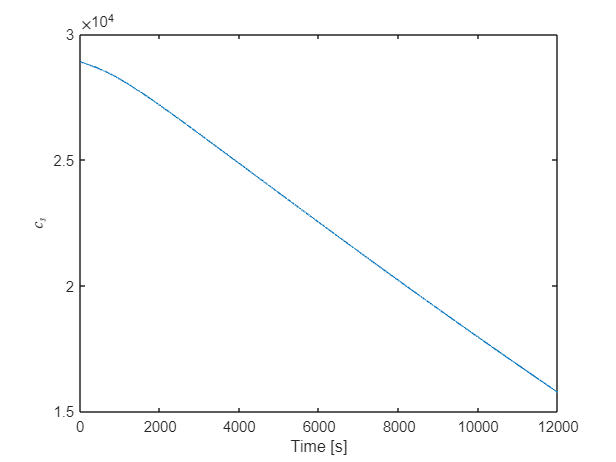

figure;
plot(out.t, out.cs_bar(1,:));
xlabel('Time [s]');
ylabel('$c_s$', 'Interpreter', 'latex');

## Example 2: Dynamic discharge with a measured current profile

Load a parameter set and a recorded current profile. `data.I` is normalised for a 1 Ah cell and is rescaled to the actual capacity `p.Cbat` (in As).

clear; clc;
load params.mat   % parameter struct `p`
load data.mat     % struct `data` with fields t [s] and I [A for a 1 Ah cell]
p.verbose = 2;    % 0 = silent, 2 = progress + timing
data.I = data.I * (p.Cbat/3600);  % scale to this cell's capacity

out = DFN([data.t data.I], 12000, 1, p);

15:38:37 Starting simulation...
15:38:46 Finished the simulation in 9.07 s 



Plot voltage, current and a representative internal state:

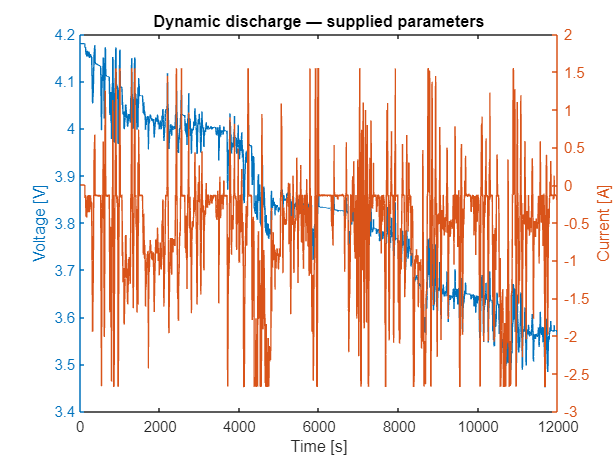

figure;
yyaxis left
plot(out.t, out.V);
ylabel('Voltage [V]');
yyaxis right
plot(out.t, out.i_app);
ylabel('Current [A]');
xlabel('Time [s]');
title('Dynamic discharge — supplied parameters');

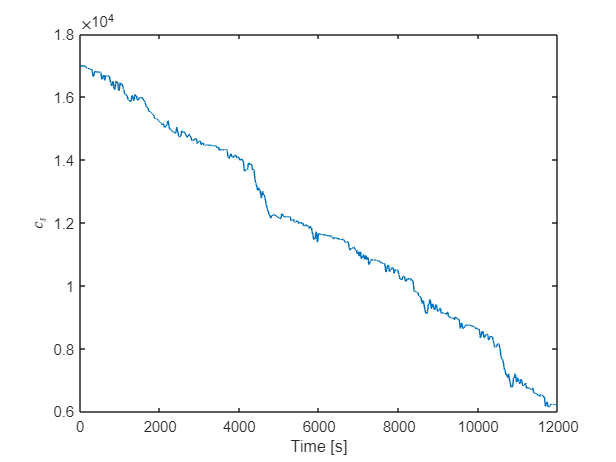


figure;
plot(out.t, out.cs_bar(1,:));
xlabel('Time [s]');
ylabel('$c_s$', 'Interpreter', 'latex');

#### Model Simplifications: a quick comparison

`p.set_simp` controls the six simplification flags. Lowering the level retains more physics at the cost of runtime. Here we compare the default (more aggressive) run against a less-simplified run on the same profile.

p.set_simp = [1, 1, 1, 1, 0, 0];   % reduced simplifications
out_simp   = DFN([data.t data.I], 12000, 1, p);

15:38:46 Starting simulation...
15:39:10 Finished the simulation in 23.81 s 



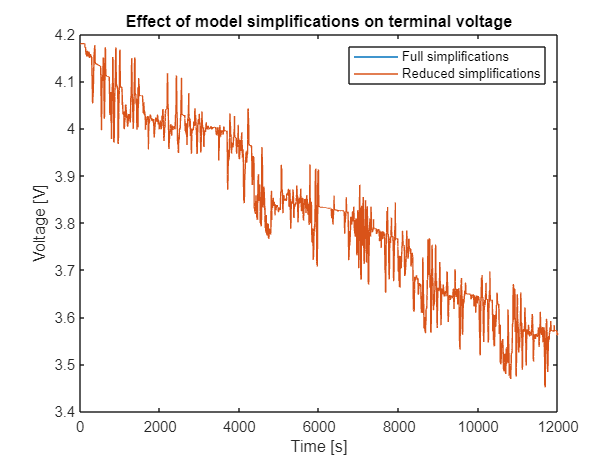

figure;
plot(out.t, out.V, out_simp.t, out_simp.V);
xlabel('Time [s]');
ylabel('Voltage [V]');
legend('Full simplifications', 'Reduced simplifications');
title('Effect of model simplifications on terminal voltage');

In the run above, the heavily simplified configuration finished in ~8 s versus ~22 s for the reduced one, with no visible difference in voltage. See [Khalik et al., 2021] for a systematic analysis.

## Example 3: Function-handle input for cycling

Providing the current as a function handle lets you implement charging algorithms or cycle profiles. The example function `cycle` (defined at the end of the script) runs:

- 1 A discharge

- 1 A CC-CV charge

- Drive-cycle discharge

- 5 A CC-CV charge

- 5 A discharge

Steps 4–5 repeat for 25 cycles before the sequence restarts.

### Cycling parameters

p.DriveCycle   = data;            % drive-cycle source (already scaled above)
p.dt           = 1;               % default step [s]
p.dt_charge    = 5;               % CC charge step [s]
p.dt_discharge = 5;               % discharge step [s]
p.dt_CV        = 1;               % CV step [s]
p.TotCycle     = 5;               % total cycles
p.VOffset      = 0;               % offset around the CV target
p.T_amb        = 273.15 + 25;     % ambient temperature [K]

% Cycling logic enforces its own limits, so widen the model's hard cut-offs.
p.Vmax  = 4.26;
p.Vmin  = 2.40;
p.i_min = 0.05;                   % CV termination current [A]

p.Kp1 = 15;                       % CV-stage PI gains
p.Ki1 = 5;

p.set_simp = [2, 2, 2, 2, 1, 0];



### Run and plot

out_cyc = DFN(@cycle, 1e5, 1, p);

15:39:11 Starting simulation...
-------------------------------------------
Time: 62834/100000 (63 %) 
i_app: 0.0502417 A
Voltage: 4.16006 V
Number of iterations for convergence: 
Cycle Number: 2 
Time elapsed: 26.06
--------------------------------------------------------------------------------------
Time: 5/100000 (


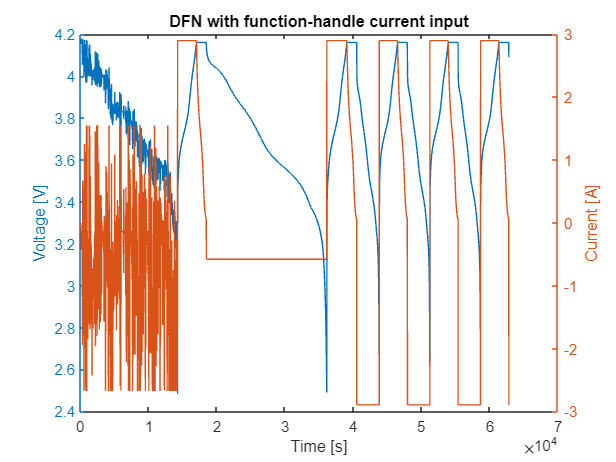

figure;
yyaxis left
plot(out_cyc.t, out_cyc.V);
ylabel('Voltage [V]');
yyaxis right
plot(out_cyc.t, out_cyc.i_app);
ylabel('Current [A]');
xlabel('Time [s]');
title('DFN with function-handle current input');

## Example 4: BPX (Battery Parameter eXchange) compatibility

BPX is the Faraday Institution's open JSON format for physics-based Li-ion parameter sets. `BPX_to_TOOFAB` (Diaz Aguilar, Lodge & Hoekstra, 2025) converts a BPX JSON into a TOOFAB parameter struct.

addpath('Parameter Sets');

parameter_set = 'NMC';   % 'NMC' or 'LFP'

switch parameter_set
    case 'NMC'
        p = BPX_to_TOOFAB('nmc_pouch_cell_BPX.json');
    case 'LFP'
        p = BPX_to_TOOFAB('lfp_18650_cell_BPX.json');
    otherwise
        error('Unknown parameter_set: %s', parameter_set);
end

BPX parameters loaded


### Step 2: Run the Simulation

Re-apply the cycling settings against the new capacity. Only the items that depend on `p` need re-setting; the timing and gain constants from Example 3 can be reused if `p` was overwritten.

load data.mat
data.I = data.I * (p.Cbat/3600);

p.DriveCycle   = data;
p.dt           = 1;
p.dt_charge    = 5;
p.dt_discharge = 5;
p.dt_CV        = 1;
p.TotCycle     = 5;
p.VOffset      = 0;
p.T_amb        = 273.15 + 25;

% Widen the cut-offs around the BPX-supplied limits.
p.Vmax  = p.Vmax + 0.1;
p.Vmin  = p.Vmin - 0.1;
p.i_min = (p.Cbat/3600) / 20;     % C/20 CV termination

p.Kp1 = 1;
p.Ki1 = 0.2;

p.set_simp = [2, 2, 2, 2, 1, 0];

out_cyc = DFN(@cycle, 1e5, 1, p);

15:39:38 Starting simulation...
15:39:58 Finished the simulation in 20.09 s 



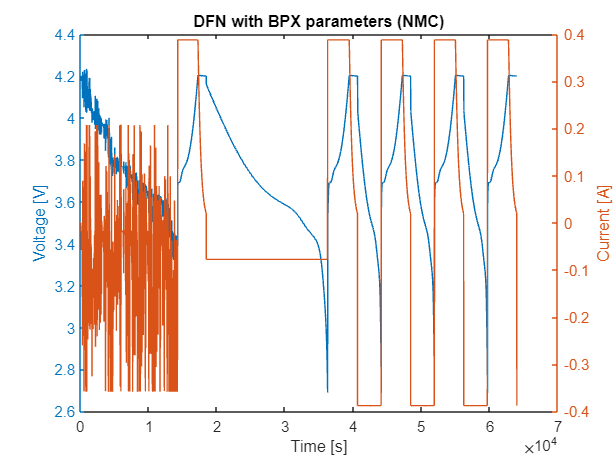


figure;
yyaxis left
plot(out_cyc.t, out_cyc.V);
ylabel('Voltage [V]');
yyaxis right
plot(out_cyc.t, out_cyc.i_app);
ylabel('Current [A]');
xlabel('Time [s]');
title(sprintf('DFN with BPX parameters (%s)', parameter_set));

## Cycling function

function [i_app_next, mem, end_simulation, dt] = cycle(k, t, i_app, V, soc, cs, ce, phis, phie, mem, p)

    % --- CV target / discharge floor ------------------------------------
    V_max = p.Vmax - 0.1 + p.VOffset;
    V_min = p.Vmin + 0.1;
    i_min = p.i_min;

    % --- PI gains for the CV stage --------------------------------------
    Kp1 = p.Kp1;
    Ki1 = p.Ki1;
    Kd1 = 0;

    end_simulation = 0;

    % --- One-time initialisation ----------------------------------------
    if k == 1
        mem.status            = 3;     % start in drive-cycle stage
        mem.CheckUp           = 1;
        mem.e                 = 0;
        mem.e2                = 0;
        mem.DriveCycleCount   = 1;
        mem.T_amb             = p.T_amb;
        mem.count             = 1;
        mem.CCcount           = 1;
        mem.CheckUpCount      = 1;
        mem.CycleNo           = 1;
        mem.TotCycle          = p.TotCycle;
        mem.Cbat_aged_current = p.Cbat;
        mem.Cbat_aged         = zeros(1, p.TotCycle);
        mem.CycleTimeStamp    = zeros(1, p.TotCycle);
    end

    % --- Stage transitions ----------------------------------------------
    % End initial discharge / drive-cycle, begin CC charge
    if (V(k) <= V_min && mem.status == 0) || mem.status == 3
        if mem.status == 3
            if V(k) <= V_min || mem.count - 1 >= p.DriveCycle.t(end)
                mem.count           = 1;
                mem.DriveCycleCount = mem.DriveCycleCount + 1;
                mem.T_amb           = p.T_amb;
                mem.status          = 1;
            end
        else
            if abs(i_app(k) + 1) < 1e-6   % was the previous discharge at -1 A?
                mem.CCcount      = 1;
                mem.CheckUpCount = mem.CheckUpCount + 1;
            end
            mem.status = 1;
        end
    end

    % End CC charge, begin CV
    if V(k) >= V_max && mem.status == 1
        mem.status  = 2;
        mem.CVcount = 1;
    end

    % End simulation on last CV
    if i_app(k) < i_min && mem.status == 2 && mem.CycleNo == mem.TotCycle
        end_simulation = 1;
    end

    % End CV, schedule next cycle (with periodic check-up)
    if i_app(k) < i_min && mem.status == 2
        mem.Cbat_aged(mem.CycleNo)      = mem.Cbat_aged_current;
        mem.CycleTimeStamp(mem.CycleNo) = k;
        mem.CycleNo                     = mem.CycleNo + 1;

        if rem(mem.CycleNo, 25) == 0
            mem.CheckUp = 1 + mem.CycleNo/25;
            mem.status  = 3;
            mem.count   = 1;
        else
            mem.status  = 0;
        end

        mem.e  = 0;
        mem.e2 = 0;
    end

    % --- Stage execution ------------------------------------------------
    switch mem.status
        case 0   % CC discharge
            mem.T_amb = p.T_amb;
            if rem(mem.CycleNo - 1, 25) == 0 || mem.CycleNo == 2
                if mem.CCcount > 1
                    mem.t_checkup(mem.CCcount) = mem.t_checkup(mem.CCcount-1) + 5;
                else
                    mem.t_checkup(1) = 1;
                end
                i_app_next = -(p.Cbat/3600) / 5;
                mem.I_checkup(mem.CCcount) = i_app_next;
                mem.CCcount = mem.CCcount + 1;
            else
                i_app_next = -p.Cbat/3600;
            end
            dt = p.dt_discharge;

        case 1   % CC charge
            mem.T_amb  = p.T_amb;
            i_app_next = p.Cbat/3600;
            dt         = p.dt_charge;

        case 2   % CV (PI controller, forward Euler)
            mem.T_amb     = p.T_amb;
            mem.e(k+1)    = V_max - V(k);
            mem.e2(k+1)   = (mem.e(k+1)  - mem.e(k))  / p.dt;
            mem.e3(k+1)   = (mem.e2(k+1) - mem.e2(k)) / p.dt;
            i_app_next    = i_app(k) + p.dt * ( Kp1*mem.e2(k+1) ...
                                              + Ki1*mem.e(k+1)  ...
                                              + Kd1*mem.e3(k+1) );
            dt = p.dt_CV;

        case 3   % Drive cycle
            i_app_next = p.DriveCycle.I(mem.count);
            mem.count  = mem.count + 1;
            dt         = 1;
    end
end


## References:

Khalik, Z., Donkers, M. C. F., & Bergveld, H. J. (2021). Model simplifications and their impact on computational complexity for an electrochemistry-based battery modeling toolbox. *Journal of Power Sources, 488*, 229427. [https://doi.org/10.1016/j.jpowsour.2020.229427](https://doi.org/10.1016/j.jpowsour.2020.229427)

Diaz Aguilar, A. M., Lodge, A. A., & Hoekstra, F. S. J. (2025). Unlocking electrochemical battery modelling: An open-source suite comparison methodology. *IFAC-PapersOnLine, 59*(5), 169–174. [https://doi.org/10.1016/j.ifacol.2025.07.100](https://doi.org/10.1016/j.ifacol.2025.07.100)

Faraday Institution. (n.d.). *About BPX*. Battery Parameter eXchange (BPX). [https://bpxstandard.com/about-bpx/](https://bpxstandard.com/about-bpx/)